# 1. Different member attributes

clear
clc
fprintf('\n=== GROUP 17 MEMBERS ATTRIBUTES ===\n');


=== GROUP 17 MEMBERS ATTRIBUTES ===


% Each group members attributes stored and saved into a single variable
NAME = ["Babra";"wycliff";"Gift";"Chris";"Vincent";"Caleb";"Edwine";"Faith";"Rhionah";"Posh"];
AGE = [20;25;31;23;22;34;26;21;19;28];
TRIBE = ["Atesot";"Musoga";"Kakwa";"Muganda";"Kejong";"Jap";"Mutoro";"Mukiga";"Munyoro";"Samia"];
HOME_DISTRICT = ["Amuria";"Kamuli";"Serori";"Mukono";"Moroto";"Tororo";"Kagadi";"Kabale";"Hoima";"Busia"];
VILLAGE = ["Acowa";"Achai";"Timo";"Mbalala";"Akwak";"Nagongera";"Busesa";"Kayoli";"Kiriatete";"Shaule"];
RELIGION = ["Catholic";"Pentecostal";"Anglican";"Catholic";"Catholic";"Anglican";"Muslim";"Anglican";"Catholic";"SDA"]

RELIGION = 10×1 string array
    "Catholic"
    "Pentecostal"
    "Anglican"
    "Catholic"
    "Catholic"
    "Anglican"
    "Muslim"
    "Anglican"
    "Catholic"
    "SDA"


COURSE = ["WAR";"WAR";"WAR";"AMI";"AMI";"MEB";"AMI";"APE";"AMI";"WAR"];
INTEREST = ["Reading";"Praying";"Research";"Reading";"Football";"Bako";"Praying";"Swimming";"Dancing";"Bako"];
FACIAL_REPRESENTATION = ["brown"; "dark brown"; "dark"; "dark brown"; "fair dark"; "fair dark"; "optimum brown"; "fair brown"; "brown" ; "fair brown";];

TABLE = table(NAME,AGE,TRIBE,HOME_DISTRICT,VILLAGE,RELIGION,COURSE,INTEREST,FACIAL_REPRESENTATION);
disp(TABLE); % displays table

      NAME       AGE      TRIBE      HOME_DISTRICT      VILLAGE        RELIGION       COURSE     INTEREST     FACIAL_REPRESENTATION
    _________    ___    _________    _____________    ___________    _____________    ______    __________    _____________________

    "Babra"      20     "Atesot"       "Amuria"       "Acowa"        "Catholic"       "WAR"     "Reading"        "brown"           
    "wycliff"    25     "Musoga"       "Kamuli"       "Achai"        "Pentecostal"    "WAR"     "Praying"        "dark brown"      
    "Gift"       31     "Kakwa"        "Serori"       "Timo"         "Anglican"       "WAR"     "Research"       "dark"            
    "Chris"      23     "Muganda"

writetable(TABLE,'Group 17 member attributes.xlsx'); %creates an excell workbook to save the attributes

# 2. Different statistical characteristic analysis of group data

% Age Statistics
fprintf('AGE Statistics: '); %Displays age statistics

AGE Statistics: 

fprintf('Mean AGE: %.2f years', mean(AGE)); %calculating the mean age of 10members and fixes it to 2 decimal places

Mean AGE: 24.90 years

fprintf('Median AGE: %.2f years', median(AGE)); %calculates the median age of 10members and fixes it 2 decimal places

Median AGE: 24.00 years

fprintf('AGE Range: %d - %d years', min(AGE), max(AGE)); %minimum and maximum age

AGE Range: 19 - 34 years

fprintf('Standard Deviation: %.2f years', std(AGE)); %standard deviation of the ages

Standard Deviation: 4.91 years

%Upper and lower quartiles
quartiles = quantile(AGE, [0.25, 0.75]);
fprintf('Lower quartile: %.2f years, Upper quartile: %.2f years', quartiles(1), quartiles(2));

Lower quartile: 21.00 years, Upper quartile: 28.00 years

## a). Categorical data distribution

% Count unique values for district frequency distribution
fprintf('District Distribution: ');

District Distribution: 

unique_districts = unique(HOME_DISTRICT); %removing dublicated values leaving only unique elements
district_counts = groupcounts(HOME_DISTRICT); %how many times a unique value appears in the data
for i = 1:length(unique_districts) % creates a vector that goes from 1 to the length of unique districts
    fprintf('  %s: %d members(s)\n', unique_districts{i}, district_counts(i)); % Prints out unique district with the number of members in each district
end

  Amuria: 1 members(s)
  Busia: 1 members(s)
  Hoima: 1 members(s)
  Kabale: 1 members(s)
  Kagadi: 1 members(s)
  Kamuli: 1 members(s)
  Moroto: 1 members(s)
  Mukono: 1 members(s)
  Serori: 1 members(s)
  Tororo: 1 members(s)



% Count unique values for course frequency distribution
fprintf('Course distribution: ');

Course distribution: 

unique_courses = unique(COURSE);
course_count = groupcounts(COURSE);
for i =1:length(unique_courses)
    fprintf(' %s: %d member(s)\n', unique_courses{i}, course_count(i));
end

 AMI: 4 member(s)
 APE: 1 member(s)
 MEB: 1 member(s)
 WAR: 4 member(s)



% Count unique values for religion frequency distribution
fprintf('Religion distribution: ');

Religion distribution: 

unique_religion = unique(RELIGION);
religion_count = groupcounts(RELIGION);
for i =1:length(unique_religion)
    fprintf(' %s: %d member(s)\n', unique_religion{i}, religion_count(i));
end

 Anglican: 3 member(s)
 Catholic: 4 member(s)
 Muslim: 1 member(s)
 Pentecostal: 1 member(s)
 SDA: 1 member(s)



% Count unique values for facial representation frequency distribution
fprintf('Facial representation distribution: ');

Facial representation distribution: 

unique_facial_rep = unique(FACIAL_REPRESENTATION);
facial_rep_count = groupcounts(FACIAL_REPRESENTATION);
for i =1:length(unique_facial_rep)
    fprintf(' %s: %d member(s)\n', unique_facial_rep{i}, facial_rep_count(i));
end

 brown: 2 member(s)
 dark: 1 member(s)
 dark brown: 2 member(s)
 fair brown: 2 member(s)
 fair dark: 2 member(s)
 optimum brown: 1 member(s)



% Count unique values for village frequency distribution
fprintf('Religion distribution: ');

Religion distribution: 

unique_village = unique(VILLAGE);
village_count = groupcounts(VILLAGE);
for i =1:length(unique_village)
    fprintf(' %s: %d member(s)\n', unique_village{i}, village_count(i));
end

 Achai: 1 member(s)
 Acowa: 1 member(s)
 Akwak: 1 member(s)
 Busesa: 1 member(s)
 Kayoli: 1 member(s)
 Kiriatete: 1 member(s)
 Mbalala: 1 member(s)
 Nagongera: 1 member(s)
 Shaule: 1 member(s)
 Timo: 1 member(s)


## b). Data Visualization and plotting

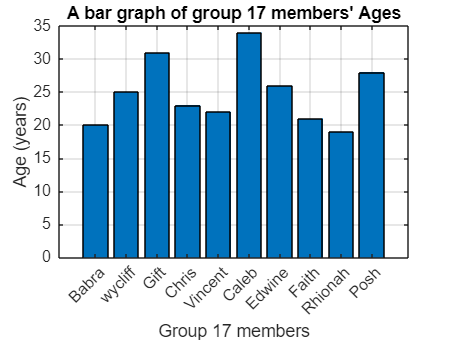

%2D bar graph for members' ages
figure; %creates new graphical window for plotting
bar(AGE);
title("A bar graph of group 17 members' Ages");
xlabel('Group 17 members');
ylabel('Age (years)');
xticklabels(NAME); %labels the horizotal axis with the name variables
xtickangle(45); %angle for the horizotal axis name variables
grid on; % enables gridlines for easy visibility
saveas(gcf,'2D_bar_graph.png'); %saves the bar graph as an image in png format

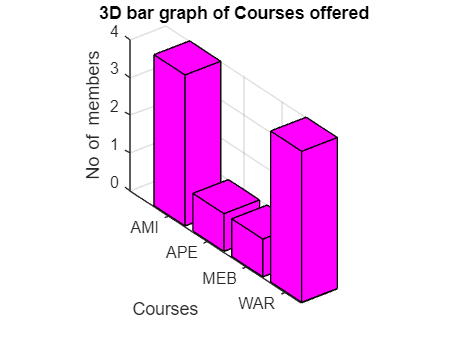


%3D bar plots
figure;
bar3(course_count, 'magenta');
title('3D bar graph of Courses offered');
zlabel('No_ of members');
yticklabels(unique_courses);
ylabel("Courses");
grid on;
saveas(gcf,'3D_bar_graph.png');

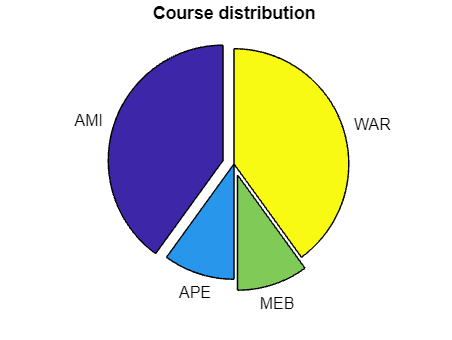


% 2D Exploded pie chart
figure;
exploded = [2,0,1,0]; %pulls AMI with a factor of 2 and MEB with a factor of 1
pie(course_count, exploded,unique_courses);
title('Course distribution');
saveas(gcf,'2Dpie_chart.png');

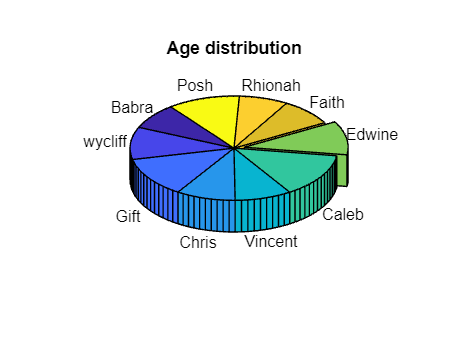


% 3D exploded pie chart
figure;
expld = [0,0,0,0,0,0,1,0,0,0];
pie3(AGE,expld,NAME);
title('Age distribution');
saveas(gcf,'3Dpie_chart.png');

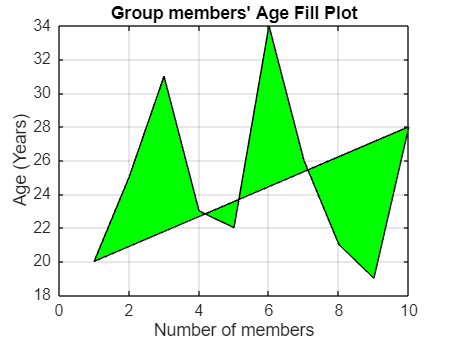


%fill plot
figure;
fill(1:10, AGE, 'g'); %fills up the area inside the plot with green
title("Group members' Age Fill Plot");
ylabel('Age (Years)');
xlabel('Number of members');
grid on;
saveas(gcf,'fill_plot.png');

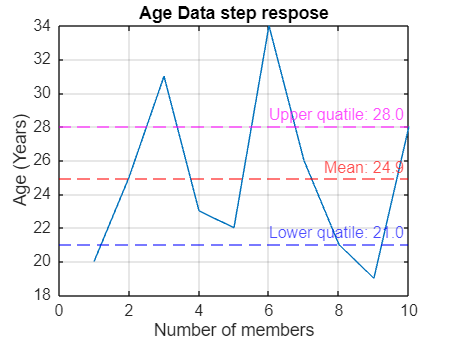


%Step respose plot
figure;
plot(AGE);
yline(mean(AGE), 'r--', sprintf('Mean: %.1f',mean(AGE))); %draws a red dotted line showing the mean age
yline(quartiles(1), 'b--', sprintf('Lower quatile: %.1f',quartiles(1))); %draws a blue dotted line showing the the lower quatile
yline(quartiles(2), 'm--', sprintf('Upper quatile: %.1f',quartiles(2))); %draws a magenta dotted line showing the upper quatile
title('Age Data step respose');
xlabel('Number of members');
ylabel('Age (Years)')
grid on;
saveas(gcf,'Step_respose_plot.png');

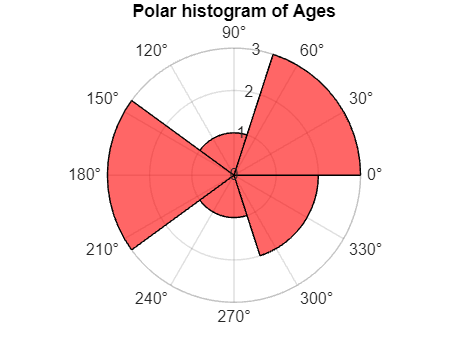


%polar histogram
figure;
polarhistogram(AGE, 5, 'Facecolor','r');
title('Polar histogram of Ages');
saveas(gcf,'polar_histogram.png');